# Wiener Filter Analysis

#### Load the images I1 and I2

load("img_restoration.mat");

#### Visualize Images

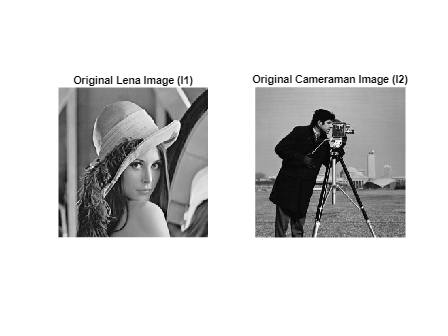

figure;
subplot(1, 2, 1); imshow(I1, []); title("Original Lena Image (I1)");
subplot(1, 2, 2); imshow(I2, []); title("Original Cameraman Image (I2)");

#### Choose one of the Images

original_image = I1;

#### Apply Linear Motion Deformation

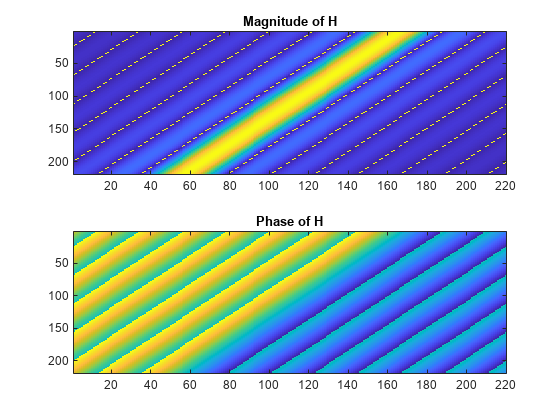

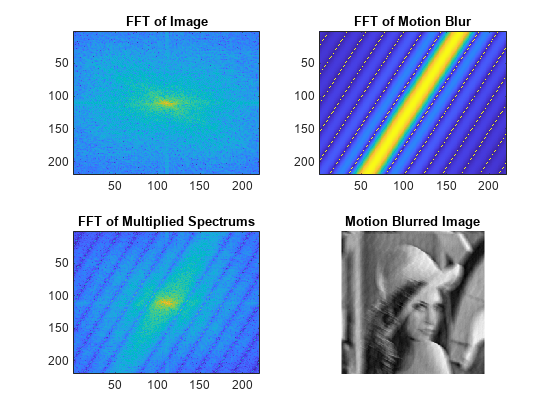

a = 10; % Horizontal motion coefficient
b = 5; % Vertical motion coefficient
T = 1; % Exposure time
[motion_blurred_image,  motion_blur_kernel_spectrum] = applyLinearMotionBlur(a, b, T, original_image, true);

#### Add Gaussian noise

mean = 0;
variance = 10;
noise = mean + sqrt(variance) * randn(size(motion_blurred_image));
noisy_motion_blurred_image = motion_blurred_image + noise;

#### Visualize Motion Blurred Noisy Image

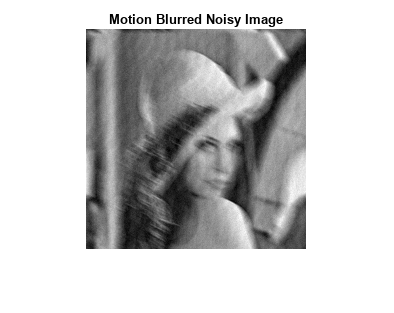

figure; imshow(noisy_motion_blurred_image, []); title("Motion Blurred Noisy Image");

#### Using Different K values Apply Wiener Filter to the Noisy Image

k = -10:0.01:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));
max_snr = 0;
min_mse = 0;
best_k = 0;
for i = 1:length(k)
    restored_image = wienerFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum, k(i), false);
    snr_db_values(i) = computeSNR_db(original_image, restored_image);
    mse_values(i) = computeMSE(original_image, restored_image);
    if (snr_db_values(i) > max_snr)
        best_restored_image = restored_image;
        min_mse = mse_values(i);
        max_snr = snr_db_values(i);
        best_k = k(i);
    end
end

#### Plot the SNR (dB) values and MSE values corresponding to different K values

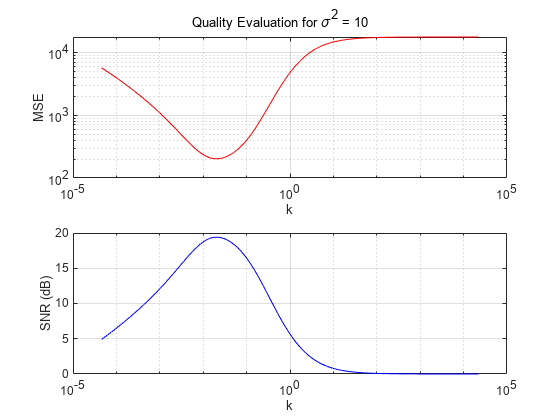

figure;
subplot(2, 1, 1); loglog(k, mse_values, "Color", "red"); xlabel("k"); ylabel("MSE"); grid on;
subplot(2, 1, 2); semilogx(k, snr_db_values, "Color", "blue"); xlabel("k"); ylabel("SNR (dB)"); grid on;
sgtitle("Quality Evaluation for \sigma^2 = " + variance);

#### Visualize the results of best K for a certain noise power

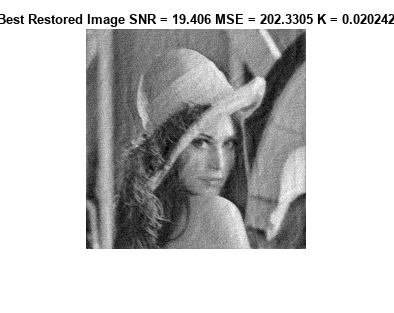

figure;
title_text = "Best Restored Image SNR = " + max_snr ...
    + " MSE = " + min_mse + " K = " + best_k;
imshow(best_restored_image, []); title(title_text);

#### Loop through various noise powers and find best K for each

varience_vec = 1:5:100;
best_k_vec = zeros(size(varience_vec));
max_snr_vec = zeros(size(varience_vec));
min_mse_vec = zeros(size(varience_vec));

for j = 1:length(varience_vec)

varience = varience_vec(j);
mean = 0;
noise = mean + sqrt(variance) * randn(size(motion_blurred_image));
noisy_motion_blurred_image = motion_blurred_image + noise;

k = -10:0.01:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));
max_snr = 0;
min_mse = 0;
best_k = 0;
for i = 1:length(k)
    restored_image = wienerFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum, k(i), false);
    snr_db_values(i) = computeSNR_db(original_image, restored_image);
    mse_values(i) = computeMSE(original_image, restored_image);
    if (snr_db_values(i) > max_snr)
        best_restored_image = restored_image;
        min_mse = mse_values(i);
        max_snr = snr_db_values(i);
        best_k = k(i);
    end
end

min_mse_vec(j) = min_mse;
max_snr_vec(j) = max_snr;
best_k_vec(j) = best_k;

end

#### Plot the metrics

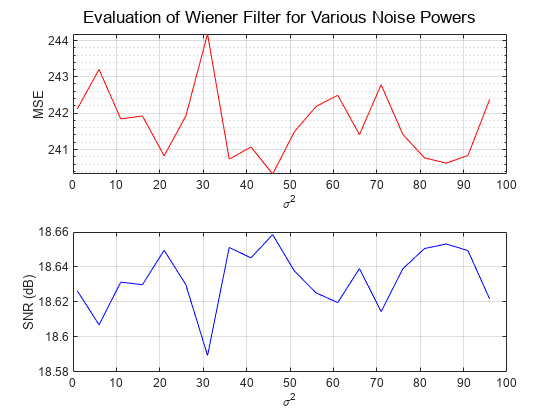

figure;
subplot(2, 1, 1); semilogy(varience_vec, min_mse_vec, "Color", "red"); xlabel("\sigma^2"); ylabel("MSE"); grid on;
subplot(2, 1, 2); plot(varience_vec, max_snr_vec, "Color", "blue"); xlabel("\sigma^2"); ylabel("SNR (dB)"); grid on;
sgtitle("Evaluation of Wiener Filter for Various Noise Powers");